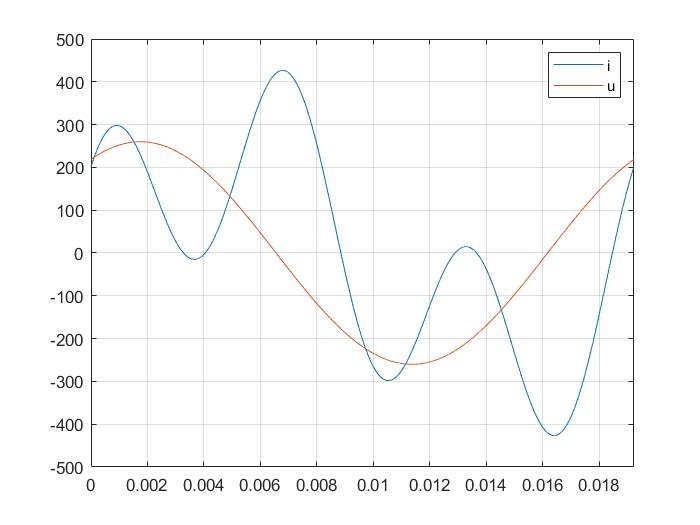

aI = 240; f = 52; % Current amplitude [A] and frequency [Hz]
w = 2*pi*f;
h = 1/f/1e4;
t = 0:h:1/f;
i = aI*sin(w*t) + aI*sin(3*w*t+1);
e = diff(i);
k = 0.16e4*240/241.2*0.9997;
u = 52*sin(w*t+1);
pit = u.*i;
plot(t, i, t, u*5); legend('i', 'u');
grid on; xlim([0,1/f]); 

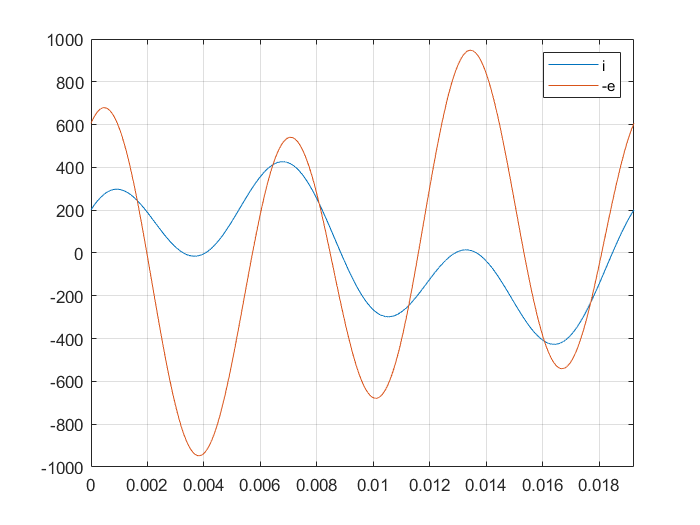

Pi = trapz(t, pit);


n = length(i) - 1;
eshift = circshift(e*k, n/4);
plot(t(1:n),i(1:n), t(1:n), -eshift); 
grid on; xlim([0,1/f]); 
legend('i', '-e');

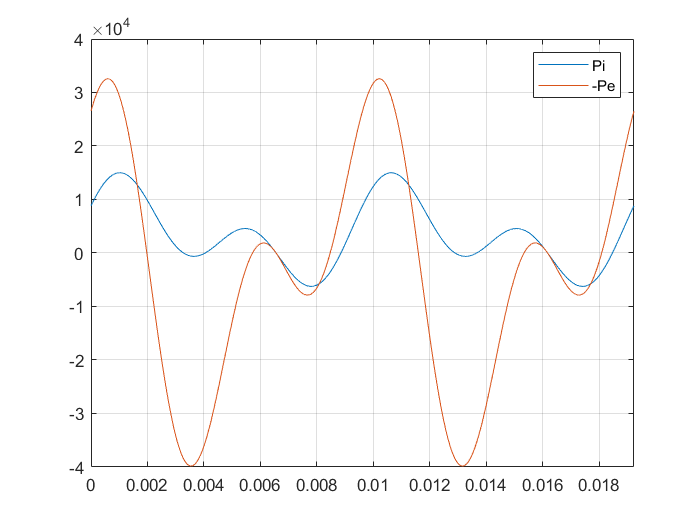

pet = u(1:n).*eshift;
Pe = trapz(t(1:n),pet);

plot(t(1:n), pit(1:n), t(1:n), -pet); legend('Pi', '-Pe');

grid on; xlim([0,1/f]); 

fprintf("Pi=%2.2f, Pe=%2.2f, error=%2.2f%%", ...
    Pi, Pe, (1-Pi/Pe)*100);

Pi=64.84, Pe=64.92, error=0.13%

fprintf("i=%3.2f, e=%3.2f, error=%2.2f%%", ...
    rms(i), rms(eshift), (1-rms(i)/rms(eshift))*100);

i=240.00, e=536.66, error=55.28%